clc, close all, clear all


Parameters

% Masses  [Kg]
M1 = 1;
M2 = 0.8;
m1 = 0.20;
m2 = 0.15;

% Lengths  [m]
L1 = 0.40;
L2 = 0.30;

% Stiffnesses  [N/m]
k1 = 50;
k2 = 30;

% Damping coefficients  [N*s/m]
c1 = 2.0;
c2 = 1;

% Torsional Stiffnesses  [N*m/rad]
kt1 = 0.30;
kt2 = 0.20;

% Gravitational Acceleration  [m/s^2]
g = 9.81;


Initial Conditions

% Initial Positions [m] and [rad]
x1_0 = -0.04;
x2_0 = 0.04;
theta1_0 = -0.10;
theta2_0 = 0.11;

% Initial Velocities [m/s] and [rad/s]
v1_0 = 0;
v2_0 = 0;
omega1_0 = 0;
omega2_0 = 0;

y0 = [x1_0; x2_0; theta1_0; theta2_0; v1_0; v2_0; omega1_0; omega2_0];


Linear System: Jacobian Matrix

A1 = -4*(k1 + k2)/(4*M1 + m1);
A2 = 4*k2/(4*M1 + m1);
A3 = 3*(m1*g*L1 + 2*kt1)/L1/(4*M1 + m1);
A4 = -4*(c1 + c2)/(4*M1 + m1);
A5 = 4*c2/(4*M1 + m1);

B1 = 4*k2/(4*M2 + m2);
B2 = -4*k2/(4*M2 + m2);
B3 = 3*(m2*g*L2 + 2*kt2)/L2/(4*M2 + m2);
B4 = 4*c2/(4*M2 + m2);
B5 = -4*c2/(4*M2 + m2);

C1 = 6*(k1 + k2)/L1/(4*M1 + m1);
C2 = -6*k2/L1/(4*M1 + m1);
C3 = -6*(M1 + m1)*(m1*g*L1 + 2*kt1)/m1/L1^2/(4*M1 + m1);
C4 = 6*(c1 + c2)/L1/(4*M1 + m1);
C5 = -6*c2/L1/(4*M1 + m1);

D1 = -6*k2/L2/(4*M2 + m2);
D2 = 6*k2/L2/(4*M2 + m2);
D3 = -6*(M2 + m2)*(m2*g*L2 + 2*kt2)/m2/L2^2/(4*M2 + m2);
D4 = -6*c2/L2/(4*M2 + m2);
D5 = 6*c2/L2/(4*M2 + m2);

J = [0  0  0  0 1  0  0 0;
     0  0  0  0 0  1  0 0;
     0  0  0  0 0  0  1 0;
     0  0  0  0 0  0  0 1;
     A1 A2 A3 0 A4 A5 0 0;
     B1 B2 0 B3 B4 B5 0 0;
     C1 C2 C3 0 C4 C5 0 0;
     D1 D2 0 D3 D4 D5 0 0];


Linearized System

B=zeros(8,1);
C=zeros(1,8);
D=zeros(1,1);

sys=ss(J,B,C,D);

Free Response

tspan=[0 20];

[~,t,x] = initial(sys,y0,tspan);

x1 = x(:,1);
x2 = x(:,2);
theta1 = x(:,3);
theta2 = x(:,4);
v1 = x(:,5);
v2 = x(:,6);
omega1 = x(:,7);
omega2 = x(:,8);


Total Kinetic Energy 

K = 0.5*(M1+m1)*v1.^2 + 0.5*(M2+m2)*v2.^2 + 0.5*(m1*L1^2/3)*omega1.^2 + 0.5*(m2*L2^2/3)*omega2.^2 + 0.5*m1*L1*cos(theta1).*v1.*omega1 + 0.5*m2*L2*cos(theta2).*v2.*omega2;


Total Potential Energy

Vg = m1*g*L1/2*(1-cos(theta1)) + m2*g*L2/2*(1-cos(theta2));
Ve = 0.5*k1*x1.^2 + 0.5*k2*(x2-x1).^2 + 0.5*kt1*theta1.^2 + 0.5*kt2*theta2.^2;
V  = Vg + Ve;


Total Mechanical Energy

E = K + V;


Work of Non Conservative Forces

Pd = c1*v1.^2 + c2*(v2-v1).^2;     % dissipated power
Wd = cumtrapz(t, Pd);


Principle of Energy Conservation

Ebal = E + Wd;

Results

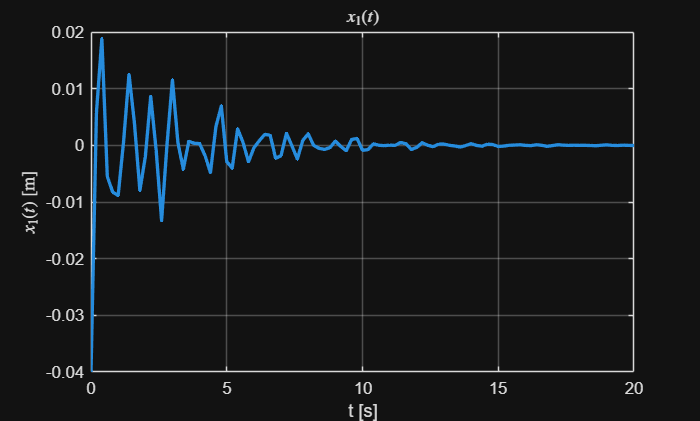

set(groot, 'DefaultLineLineWidth', 2);

figure;
plot(t,x1),title('$x_1(t)$',Interpreter='latex'),xlabel('t [s]'), ylabel('$x_1(t)$ [m]',Interpreter='latex'), grid

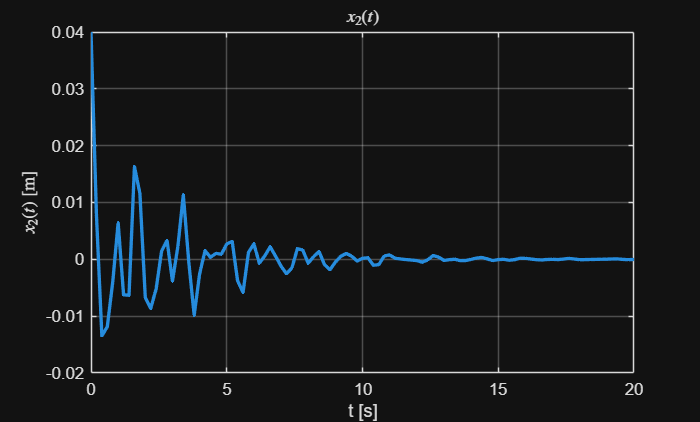

figure;
plot(t,x2),title('$x_2(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$x_2(t)$ [m]',Interpreter='latex'),grid

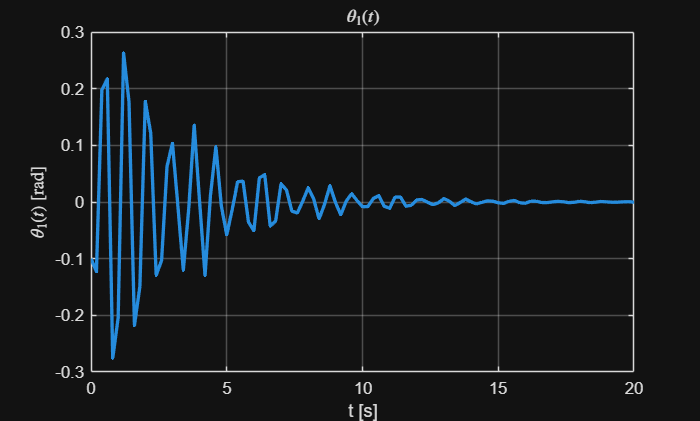


figure;
plot(t,theta1),title('$\theta_1(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$\theta_1(t)$ [rad]',Interpreter='latex'),grid

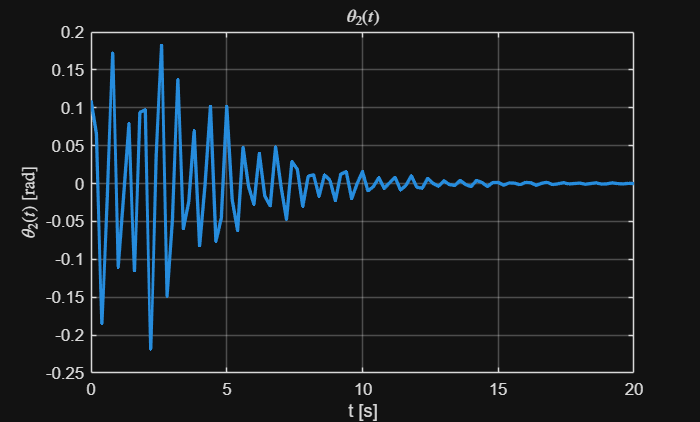

figure;
plot(t,theta2),title('$\theta_2(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$\theta_2(t)$ [rad]',Interpreter='latex'),grid

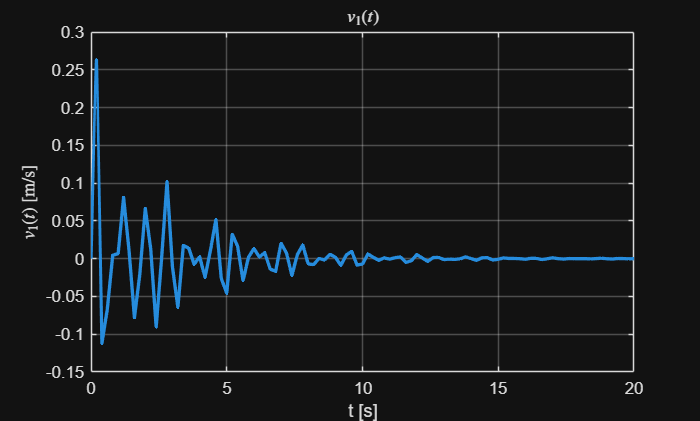


figure;
plot(t,v1),title('$v_1(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$v_1(t)$ [m/s]',Interpreter='latex'),grid

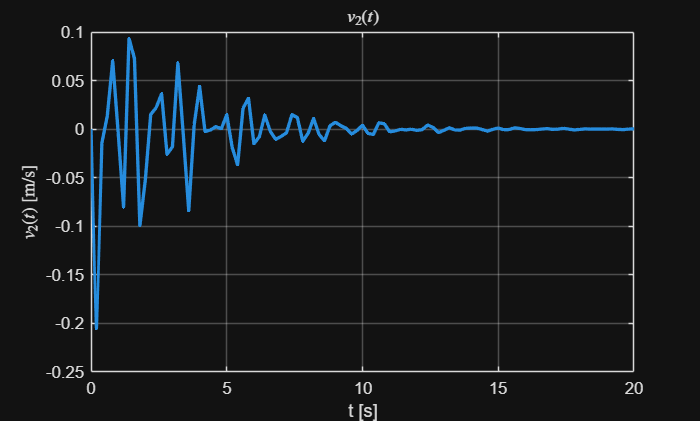


figure;
plot(t,v2),title('$v_2(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$v_2(t)$ [m/s]',Interpreter='latex'),grid

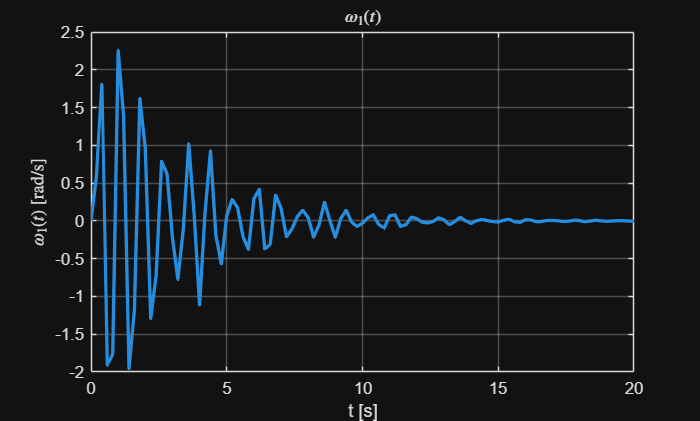


figure;
plot(t,omega1),title('$\omega_1(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$\omega_1(t)$ [rad/s]',Interpreter='latex'),grid

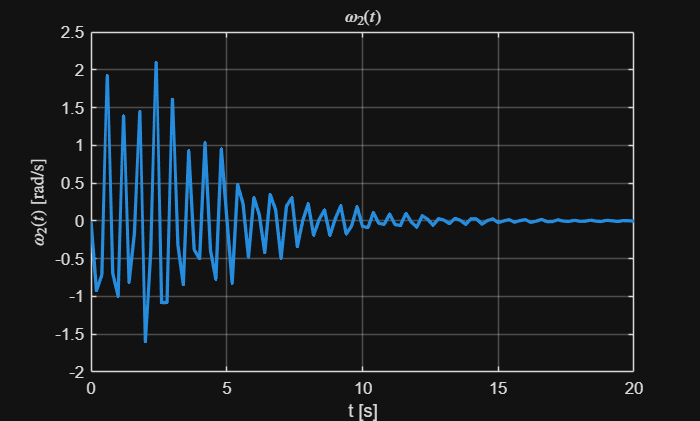


figure;
plot(t,omega2),title('$\omega_2(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$\omega_2(t)$ [rad/s]',Interpreter='latex'),grid

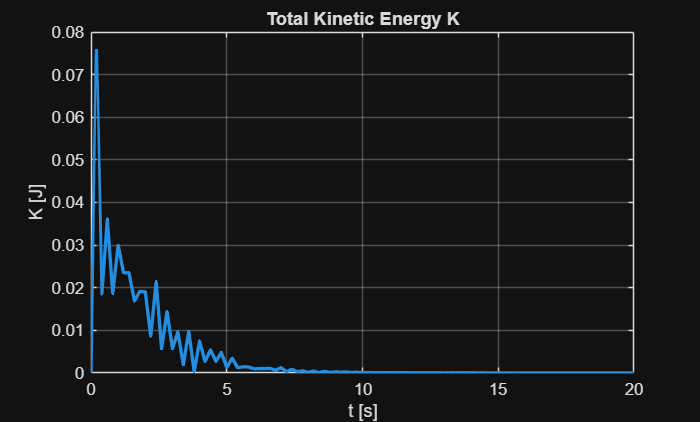


figure;
plot(t,K), title('Total Kinetic Energy K'),xlabel('t [s]'),ylabel('K [J]'),grid

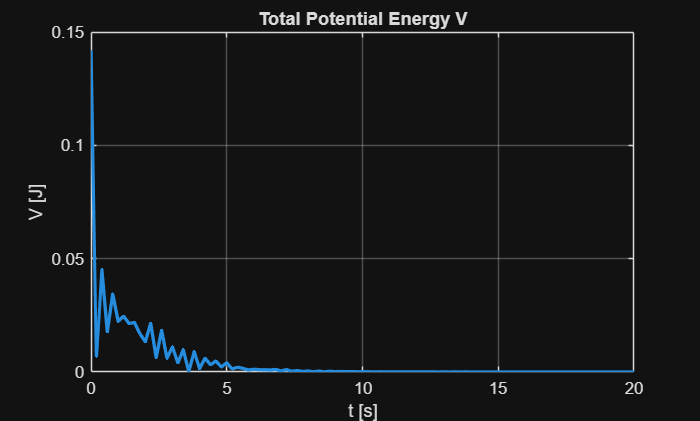


figure;
plot(t,V),title('Total Potential Energy V'),xlabel('t [s]'),ylabel('V [J]'),grid

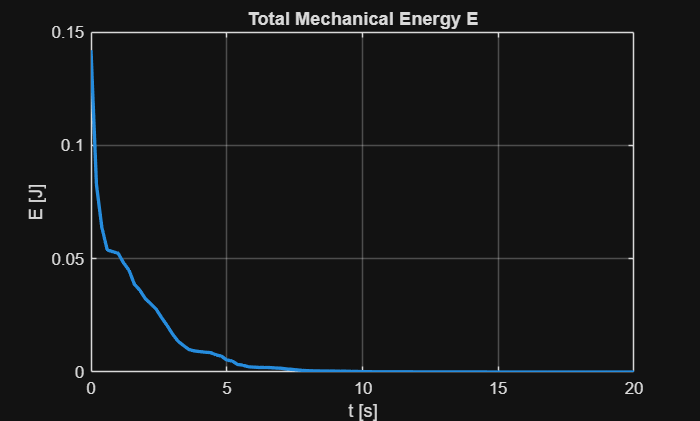


figure;
plot(t,E),title('Total Mechanical Energy E'),xlabel('t [s]'),ylabel('E [J]'),grid

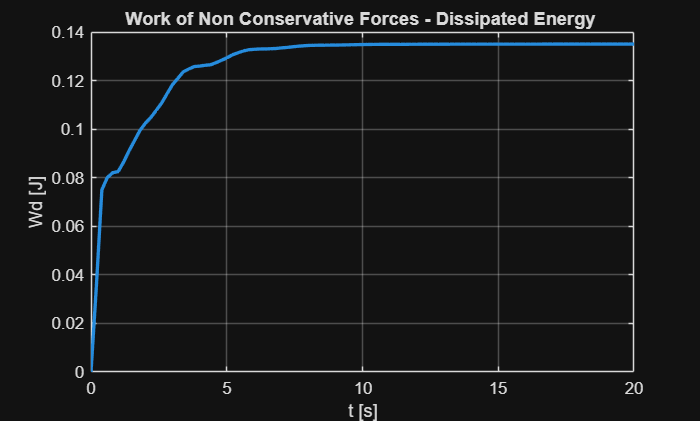


figure;
plot(t,Wd),title('Work of Non Conservative Forces - Dissipated Energy '),xlabel('t [s]'),ylabel('Wd [J]'),grid

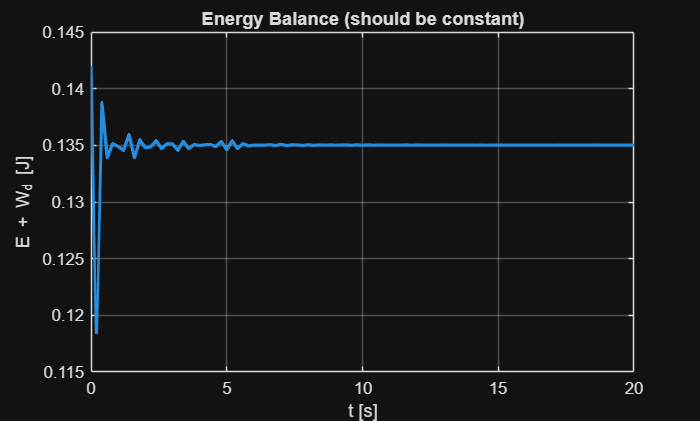


figure;
plot(t,Ebal),title('Energy Balance (should be constant)'),xlabel('t [s]'),ylabel('E + W_d [J]'),grid

Stability Analysis

% Eigenvalues of the Jacobian Matrix
lambda=eig(J)

lambda =   -1.0838 +10.6061i
  -1.0838 -10.6061i
  -0.3317 +10.1741i
  -0.3317 -10.1741i
  -0.3277 + 7.5022i
  -0.3277 - 7.5022i
  -0.2824 + 3.9379i
  -0.2824 - 3.9379i
